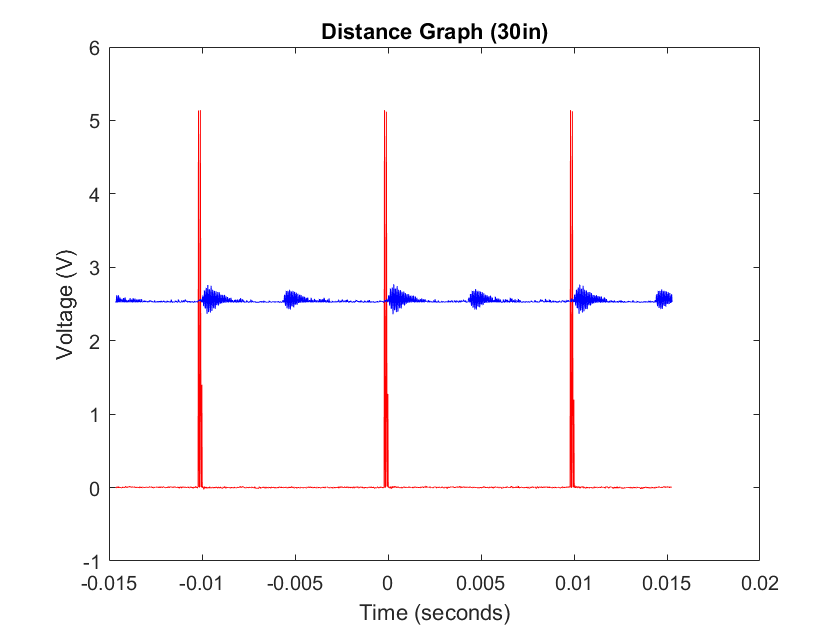

bode_data = csvread('data/data_73.csv',4);
t1 = bode_data((1:end),1);
ch1 = bode_data((1:end),2);
t2 = bode_data((1:end),3);
ch2 = bode_data((1:end),4);

clf
plot(t1,ch1,'r')
hold on
plot(t2,ch2,'b')
title("Distance Graph (30in)")
xlabel("Time (seconds)")
ylabel("Voltage (V)")

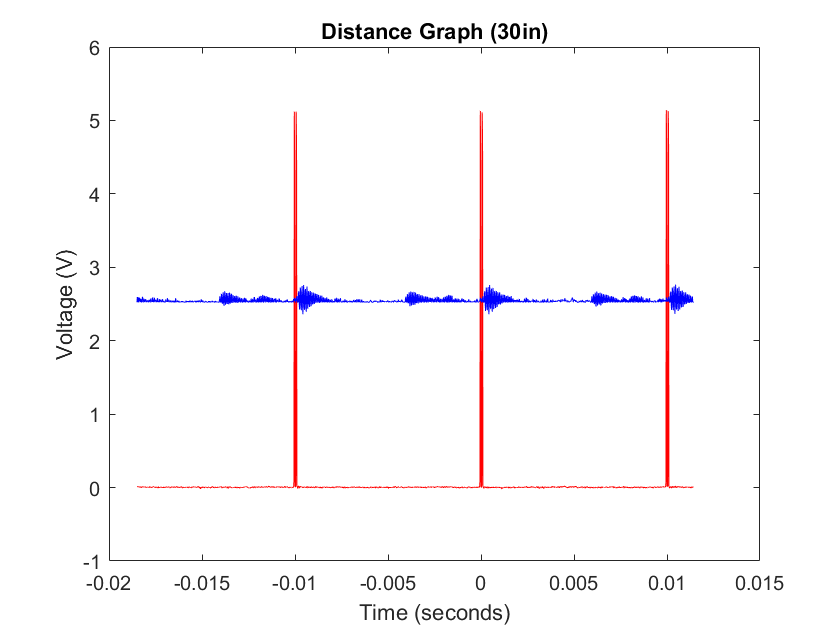

bode_data = csvread('data/data_93.csv',4);
t1 = bode_data((1:end),1);
ch1 = bode_data((1:end),2);
t2 = bode_data((1:end),3);
ch2 = bode_data((1:end),4);

clf
plot(t1,ch1,'r')
hold on
plot(t2,ch2,'b')
title("Distance Graph (30in)")
xlabel("Time (seconds)")
ylabel("Voltage (V)")

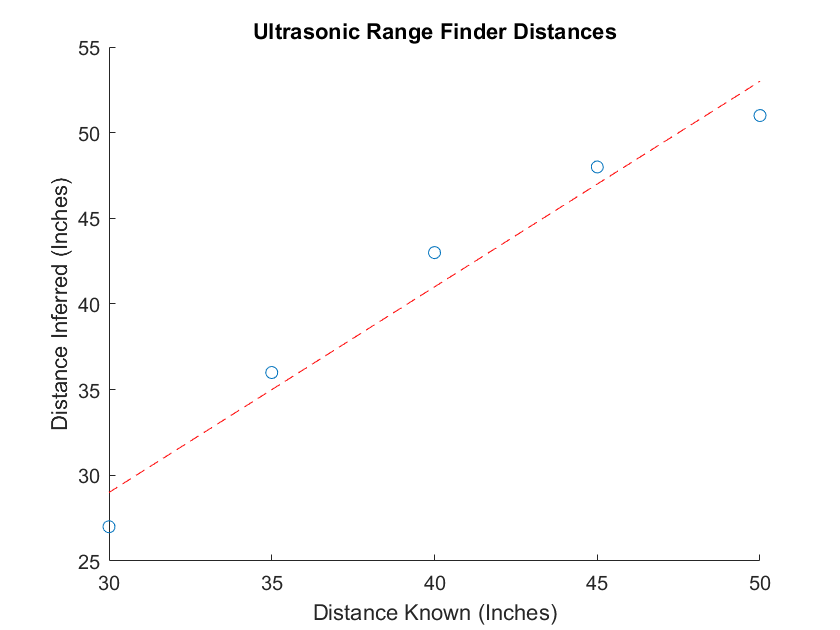

clf
xlim([20 60])
real = [30,35,40,45,50];
inferred = [27,36,43,48,51];
scatter(real,inferred);
p = polyfit(real,inferred,1);
f = polyval(p,real);
hold on
plot(real,f,'--r')
title("Ultrasonic Range Finder Distances")
xlabel("Distance Known (Inches)")
ylabel("Distance Inferred (Inches)")